% 无偏预测变量重要性估计
% 加载 carsmall 数据集。 考虑一个模型，该模型根据汽车的加速度、气缸数、发动机排量、马力、制造商、
% 车型年份和重量来预测汽车的平均燃油经济性。
% 将 Cylinders、Mfg 和 Model_Year 视为分类变量。

% Unbiased Predictor Importance Estimates
% Load the carsmall data set. Consider a model that predicts the mean fuel economy of a car 
% given its acceleration, number of cylinders, engine displacement, horsepower, manufacturer, 
% model year, and weight. Consider Cylinders, Mfg, and Model_Year as categorical variables.
load carsmall
Cylinders = categorical(Cylinders);
Mfg = categorical(cellstr(Mfg));
Model_Year = categorical(Model_Year);
X = table(Acceleration,Cylinders,Displacement,Horsepower,Mfg,...
    Model_Year,Weight,MPG);

% 显示分类变量中表示的类别数。
% Display the number of categories represented in the categorical variables.
numCylinders = numel(categories(Cylinders))

numCylinders = 3

numMfg = numel(categories(Mfg))

numMfg = 28

numModelYear = numel(categories(Model_Year))

numModelYear = 3

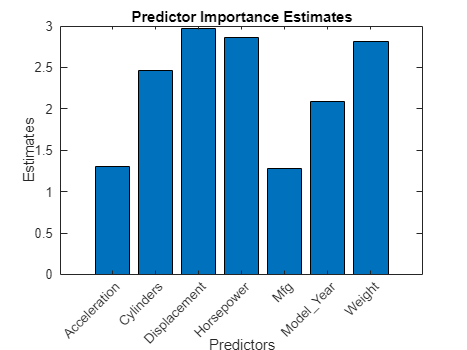


% 因为只有 Cylinders 和 Model_Year 有 3 个类别，标准 CART，predictor-splitting 
% 算法更喜欢在两个连续的变量上拆分。
% Because there are 3 categories only in Cylinders and Model_Year, 
% the standard CART, predictor-splitting algorithm prefers splitting a continuous predictor 
% over these two variables.


% 使用整个数据集训练回归树。 
% 要种植无偏树，请指定使用曲率（curvature）测试来分割预测变量。 
% 由于数据中存在缺失值，请指定使用代理拆分。
% Train a regression tree using the entire data set. 
% To grow unbiased trees, specify usage of the curvature test for splitting predictors. 
% Because there are missing values in the data, specify usage of surrogate splits.
Mdl = fitrtree(X,'MPG','PredictorSelection','curvature','Surrogate','on');


% 通过对由于每个预测变量的分裂而导致的风险变化求和并将总和除以分支节点的数量来估计预测变量的重要性值。
% 使用条形图比较估计值。 
% Estimate predictor importance values by summing changes in the risk 
% due to splits on every predictor and dividing the sum by the number of branch nodes. 
% Compare the estimates using a bar graph.
imp = predictorImportance(Mdl);

figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = Mdl.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';


% 本例中，排量是最重要的预测因素，其次是马力。
% In this case, Displacement is the most important predictor, followed by Horsepower.